# 1 DOF Cell Model in plane strain

## Data

clear all; close all; clc;
set_env;
addpath("Functions and Scripts\");
addpath("1DOF\");
load("cell_1dof_pstrain.mat")

% Data
eps1_max = 0.05;
% Symbolic variables ------------------------------------------------
% Geometry of the capacitor
syms x l_0 tf_0 dtf xi xi_0
syms epsilon_1(x) sigma_1(x) sigma_2(x) epsilon1_max

% syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)
% makeassumptions

## Equations

% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f;


w = pstrain_1dof.w

$$w = w_{0}$$

t_p = pstrain_1dof.t_p

$$t\_p = {\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)$$

l = pstrain_1dof.l

$$l = l_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)$$

A = pstrain_1dof.A

$$A = l_{0}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)$$

C_str = pstrain_1dof.C

$$C\_str(x) = \left\{ \begin{array}{cl} \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}} & \text{ if }x\leq {\mathrm{tf}}_{0}+\frac{1}{10000000000}\\ \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x} & \text{ if }{\mathrm{tf}}_{0}+\frac{1}{10000000000}<x \end{array}\right.$$

Vol = pstrain_1dof.Vol

$$Vol = 2\,l_{0}\,{\mathrm{tp}}_{0}\,w_{0}+w_{0}\,x\,\xi_{0}-\frac{l_{0}\,w_{0}\,\left({\mathrm{tf}}_{0}-x\right)}{2}$$

Vol_0 = pstrain_1dof.Vol_0

$$Vol\_0 = 2\,l_{0}\,{\mathrm{tp}}_{0}\,w_{0}$$


pstrain = sstrain1(pstrain_1dof, "PSTRAIN");
C = pstrain.C;
Vmax = pstrain.Vmax;
Uel = pstrain.Uel;
F = pstrain.F;
FVmax = pstrain.FVmax;
FVmin = pstrain.FVmin;

% Range limit
x_min = vpa(sdata1(pstrain.x_min), 4)

$$x\_min = 1.0e-5$$

x_max = subs(sstrain1(pstrain.x_max), epsilon1_max, eps1_max);
x_max = vpa(sdata1(rhs(isolate(x_max, x))), 4)

$$x\_max = 0.01602$$

x_minmax = [double(x_min) double(x_max)];


## Capacitance

% Min capacitance
Cmin = vpa(subs(sdata1(C), x, x_max), 4)

$$Cmin(x) = 2.271e-11$$


% Max C
Cmax = vpa(subs(sdata1(C), x, sdata1(tf_0)), 4)

$$Cmax(x) = 1.202e-9$$

% Plot x - C(x)
myfig(1,"x - C(x)");

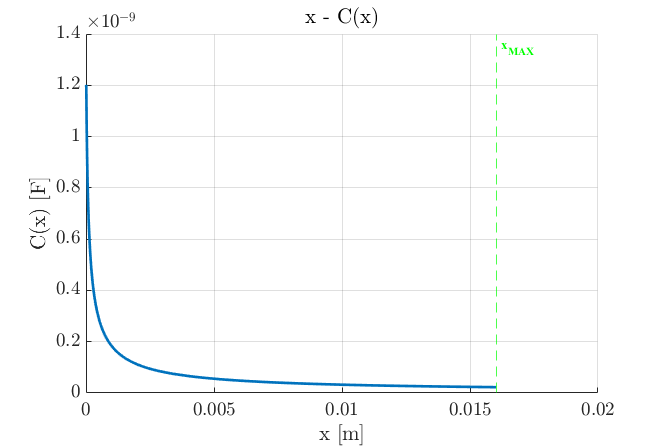

hold on; 
fplot(x, sdata1(C(x)), x_minmax, 'LineWidth', 2)
myxline(double(sdata1(x_max)), "x_{MAX}")
hold off
title("x - C(x)")
xlabel("x [m]")
ylabel("C(x) [F]")

## Max voltage

% Max voltage
% Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

% Plot x - Vmax(x)
myfig(2,"x - Vmax(x)");

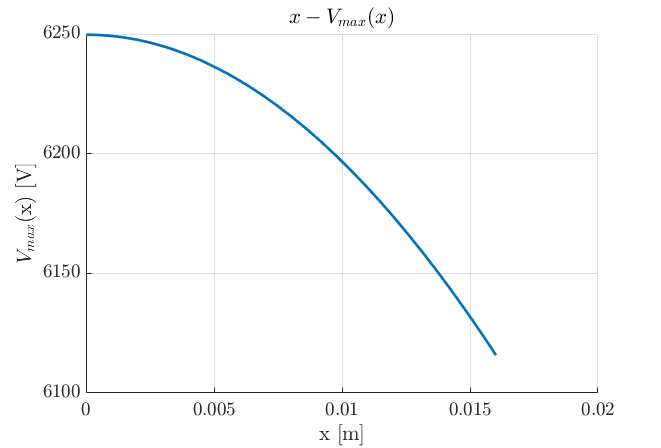

fplot(x, sdata1(Vmax(x)), x_minmax, 'LineWidth', 2)
title("$x - V_{max}(x)$")
xlabel("x [m]")
ylabel("$V_{max}$(x) [V]")

## Force

% Redefine x limits
x_range = double(x_min:1e-5:x_max);
FVmax_vec = double(subs(sdata1(FVmax),x_range));
[fvmax_peak, idx] = findpeaks(FVmax_vec);
x_min_eff = x_range(idx);
x_range_eff = double(x_min_eff:1e-5:x_max);

FVmax_vec = double(subs(sdata1(FVmax), x_range_eff));
FVmin_vec = double(subs(sdata1(FVmin), x_range_eff));

% Plot x - F(x) 
myfig(3,"x - F(x)");

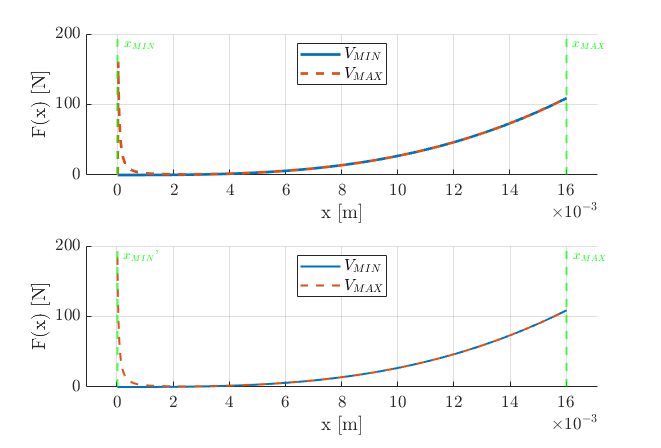

title("x - F(x)")
subplot(2,1,1); hold on
fplot(x, sdata1(FVmin), x_minmax, 'LineWidth', 2, 'DisplayName', '$V_{MIN}$')
fplot(x, sdata1(real(FVmax)), x_minmax, '--', 'LineWidth', 2, 'DisplayName', '$V_{MAX}$')
plot_xminmax(x_range(1), x_range(end))
legend("Location","north")
addlabels("x [m]", "F(x) [N]"); xlim("padded")

subplot(2,1,2); hold on
plot(x_range_eff, FVmin_vec, 'LineWidth', 1.5, 'DisplayName', "$V_{MIN}$")
plot(x_range_eff, real(FVmax_vec),'--', 'LineWidth', 1.5, 'DisplayName', "$V_{MAX}$")
plot_xminmax(x_range_eff(1), x_range_eff(end), "$x_{MIN}$'");
legend("Location", "north")
addlabels("x [m]", "F(x) [N]"); xlim("padded")

## Energy and energy density from x - F(x) varying xmax

Uel_xmax = zeros(length(x_range_eff),1);
uel_xmax = zeros(length(x_range_eff),1);
Vol_tmp = sdata1(Vol);
for i = 1:length(x_range_eff)
    Uel_xmax(i) = trapz(x_range_eff(1:i), FVmax_vec(1:i),2) - trapz(x_range_eff(1:i), FVmin_vec(1:i),2);
    uel_xmax(i) = Uel_xmax(i) / subs(Vol_tmp, x, x_range_eff(i));
end

myfig(4, "x_max / l_0 - Uel | uel"); hold on

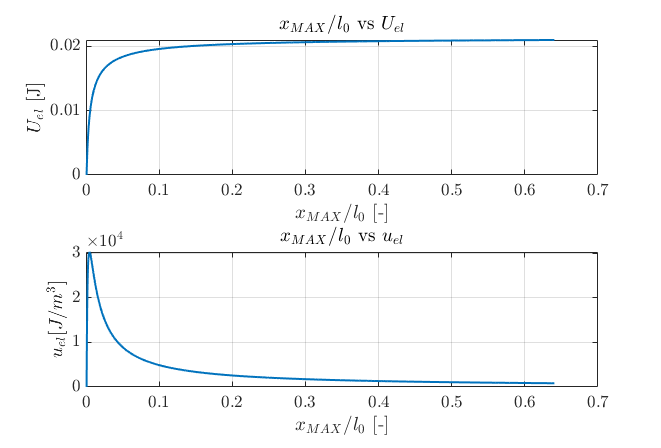

subplot(2,1,1)
plot(x_range_eff / sdata1(l_0), Uel_xmax, 'LineWidth', 1.5)
addlabels("$x_{MAX} / l_0$ [-]", "$U_{el}$ [J]", "$x_{MAX} / l_0$ vs $U_{el}$")

subplot(2,1,2)
plot(x_range_eff / sdata1(l_0), uel_xmax, 'LineWidth', 1.5)
addlabels("$x_{MAX} / l_0$ [-]", "$u_{el} [J/m^3]$", "$x_{MAX} / l_0$ vs $u_{el}$")

## Q - V

% Plot Q - V
C_vec = double(subs(sdata1(C), x, x_range_eff));
Vmax_vec = double(subs(sdata1(Vmax), x, x_range_eff));
Q_vec = C_vec .* Vmax_vec;
C_min_val = C_vec(end);
C_max_val = C_vec(1);
V_vec = linspace(0, min(Vmax_vec), 100);
Qmaxstr = double(V_vec * C_min_val);
Qminstr = double(V_vec * C_max_val);

myfig(5,"Q - V");

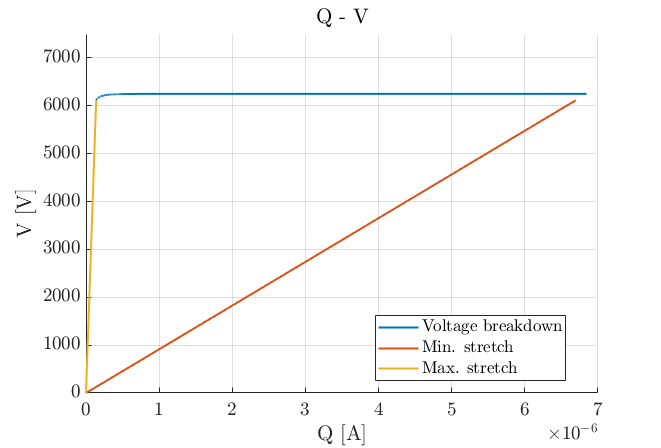

hold on
plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
plot(Qminstr, V_vec, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
plot(Qmaxstr, V_vec, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
legend('Location','best')
xlabel("Q [A]")
ylabel("V [V]")
ylim([0, 1.2 * max(Vmax_vec)])
title("Q - V")
hold off

## Energy from x - F and Q - V

Uel_Fx = trapz(x_range_eff, FVmax_vec,2) - trapz(x_range_eff, FVmin_vec,2)

Uel_Fx = 0.0210

Uel_QV = trapz(Qmaxstr, V_vec) + trapz(sort(Q_vec,'ascend'), Vmax_vec) - trapz(Qminstr, V_vec)

Uel_QV = 0.0210

% Save results
Uel_vec = double(subs(sdata1(Uel), x, x_range_eff));

res_1dof_pstrain.x_range_eff = x_range_eff;
res_1dof_pstrain.C_vec = C_vec;
res_1dof_pstrain.Vmax_vec = Vmax_vec;
res_1dof_pstrain.Uel_vec = Uel_vec;
res_1dof_pstrain.FVmin_vec = FVmin_vec;
res_1dof_pstrain.FVmax_vec = FVmax_vec;
res_1dof_pstrain.Uel_Fx = Uel_Fx;
res_1dof_pstrain.Uel_QV = Uel_QV;
res_1dof_pstrain.Uel_xmax = Uel_xmax;
res_1dof_pstrain.uel_xmax = uel_xmax;
res_1dof_pstrain.Cmin = C_vec(end);
res_1dof_pstrain.Cmax = C_vec(1);
res_1dof_pstrain.Q_vec = Q_vec;
res_1dof_pstrain.V_vec = V_vec;
res_1dof_pstrain.Qmaxstr = Qmaxstr;
res_1dof_pstrain.Qminstr = Qminstr;

save("1DOF\res_1dof_pstrain.mat", "res_1dof_pstrain")



